# Pressure Validation

## Infinite Channel using Pozrikidis (2010) Formulation

**Goal:** Validate the pressure computation at the wall in the permeable region.

Channel set-up:

- $x\in[0,L+2c]$, permeable for $x\in[c,L+c]$

- 
$$y\in[0,2H]$$


Note that the exact solution in this region is

$p_T(x) = \gamma\sinh(\alpha(x-x_m)),\quad x_m=\frac{L+2c}2,\quad \alpha^2 = \frac{3\mu {\rm Da}}{H^3}$ along $y=0$ and $y=2H$.

**Plan:** Compute pressure using MRS/SD and compare along the walls with $c\leq x\leq L+c$.

clear
close all 

addpath('./stokeslets_codes'); 


method_for_plots = 'St+SD Pozrikidis Set-up';
%set Darcy number
Da = 0.5;
%viscosity
mu = 1; 
% Regularization parameter
blob_num = 2; % blob choice
ep_factor = 1; 
ep_d_factor = 6; 
%C = 0.04*5.75; % constant for beta_value; 
C = 0.39; %constant for beta_value when V = 0 (velocity for Step 1 permeable) 
% Poiseuille flow strength
pL=10;
% chi in PC paper: "dimensionless coeff. determining exit flow rate"
exit_rate = 1;
G = 10; % !*Need to figure out exactly what this value should be*! Related to pL

% Number of source and target points
N = 160; % Number of source points (along top  and bottom boundaries)
Nx2 = 20; % Number of target points in y direction for full channel calc
Nx1 = 500;%floor(2*pi*Nx2); % Number of target points in x direction for full channel calc

% Setting forces and computing velocity 
% Channel geometry

L = 4; % length of permeable portion of the channel
H = 1; % radius of the channel
c = 2*H; % extension length of the channel

xmin = 0;
xmax = L+2*c;
ymin = 0;
ymax = 2*H;

scalefactor = 0.05; % for the boundary velocity figures (why?)

% Discretization step
ds_x = (xmax - xmin)/N;
ds_y = (ymax - ymin)/( ceil((ymax - ymin)/ds_x));

% Define blob size based on wall discretization 
ep = ds_y*ep_factor;
ep_d =ep*ep_d_factor; 

% beta value based on Da, epsilon, and C
beta_value = Da*ep*C;

%discretization step of top/bottom walls
stb = xmin+ds_x/2:ds_x:xmax-ds_x/2;
stb = stb';
%discretization step of left/right wall (inlet/outlet)
slr = ymin+ds_y/2:ds_y:ymax-ds_y/2;
slr = slr';

% Define coordinates on each wall (x-coord,y-coord) (source points)
y1_top = stb;   y2_top = ymax*ones(size(stb)); % top wall coordinates (y1_top,y2_top)
y1_bot = stb;   y2_bot = ymin*ones(size(stb)); % bottom wall coordinates (y1_bot,y2_bot)
y1_left = xmin*ones(size(slr));   y2_left = slr; % left wall coordinates (y1_left,y2_left)
y1_right = xmax*ones(size(slr));   y2_right = slr; % right wall coordinates (y1_right,y2_right)
y1 = [y1_top; y1_bot; y1_left; y1_right]; %x-coordinates of all boundary points
y2 = [y2_top; y2_bot; y2_left; y2_right]; %y-coordinates of all boundary points

% Define normal vectors
normals_top = zeros(length(stb),2); % unit normals for top:
normals_top(:,2) = 1;
normals_bot = zeros(length(stb),2); % unit normals for bottom
normals_bot(:,2) = -1;
normals_left = zeros(length(slr),2); % unit normals for left  wall 
normals_left(:,1) = -1;
normals_right = zeros(length(slr),2); % unit normals for right wall 
normals_right(:,1) = 1;

% normals on full boundary
normals = [normals_top; normals_bot; normals_left; normals_right];

% Define quadrature weights cooresponding to wall coordinates.
% Currently using midpoint rule.
% Weights for targets/sources at corners and just outside inlet/outlet are
% set to ds_y (possibly not correct) but will be divided out so shouldn't cause issues.
wt = [ds_x*ones(size(y1_top)); ds_x*ones(size(y1_bot)); ds_y*ones(size(y1_left)); ds_y*ones(size(y1_right))];

% No slip at top and bottom
u1_top_exact = zeros(size(y1_top)); u2_top_exact = zeros(size(y2_top));
u1_bot_exact = zeros(size(y1_bot)); u2_bot_exact = zeros(size(y2_bot));
% Poiseuille flow at inlet and outlet
u_pois = -pL*(y2_left - ymin).*(y2_left - ymax);%/2/mu;
u1_left_exact = u_pois;
u1_right_exact = exit_rate*u_pois;
u2_left_exact = zeros(size(slr));
u2_right_exact = zeros(size(slr));

% Set zero velocity contribution from stokeslets on permeable parts
u1 = [u1_top_exact; u1_bot_exact; u1_left_exact; u1_right_exact];
u2 = [u2_top_exact; u2_bot_exact; u2_left_exact; u2_right_exact];

idx = find(c < y1 & y1 < L+c);
beta = zeros(length(y1),1);
beta(idx) = beta_value;

% STEP 1: Find g-force distribution due to St+SD on solid walls and SD (no
% Stokeslets) on permeable walls
%[g] = RegStokeslets2D_velocityto_gforce_permeable([y1,y2],[y1,y2],...
%    [u1,u2], ep, mu, blob_num, idx, beta, normals, wt);
[g] = RegStokeslets2D_velocityto_gforce_SK([y1,y2], [y1,y2], [u1,u2],ep,ep_d,mu,blob_num, idx, beta, normals, wt); 

log10 of condition number of Mat: 3.5271
condition number of Mat+D: 3386.8222
size of Mat+D: 800  800
log10 of condition number of Mat+D: 4.3182
condition number of Mat+D: 20806.5437
size of Mat+D: 800  800



% Boundary points for permeable section
y1b=y1(idx);
y2b=y2(idx);

% Inputs to function are source, g force, target, ...
[u_perm] = RegStokeslets2D_gtovelocity([y1,y2], g, [y1b,y2b], ep_d, mu, blob_num, beta, normals, wt);
u_perm1 = u_perm(:,1);
u_perm2 = u_perm(:,2);

% Replace the placeholder zeros in u1,u2 with the velocities
% [zeros(size(u1_top_exact)); zeros(size(u1_bot_exact)); u1_left_exact; u1_right_exact; zeros(size(u1_corner_exact))]; %x-coordinates of all boundary velocities
u1(idx) = u_perm1;
u2(idx) = u_perm2;


% Step 3: Use boundary velocities to solve for forces on boundary

% Now that the missing velocities are recovered, steps 3-4 are the regular
% "Stokeslet" problem, given boundary velocities, find boundary forces,
% then find channel velocities.
ftemp = RegStokeslets2D_velocitytoforce_KK([y1,y2], [y1,y2], [u1,u2], ep, mu, blob_num,wt);

log10 of condition number of Mat: 3.5298
condition number of Mat+D: 3311.3865
size of Mat+D: 800  800


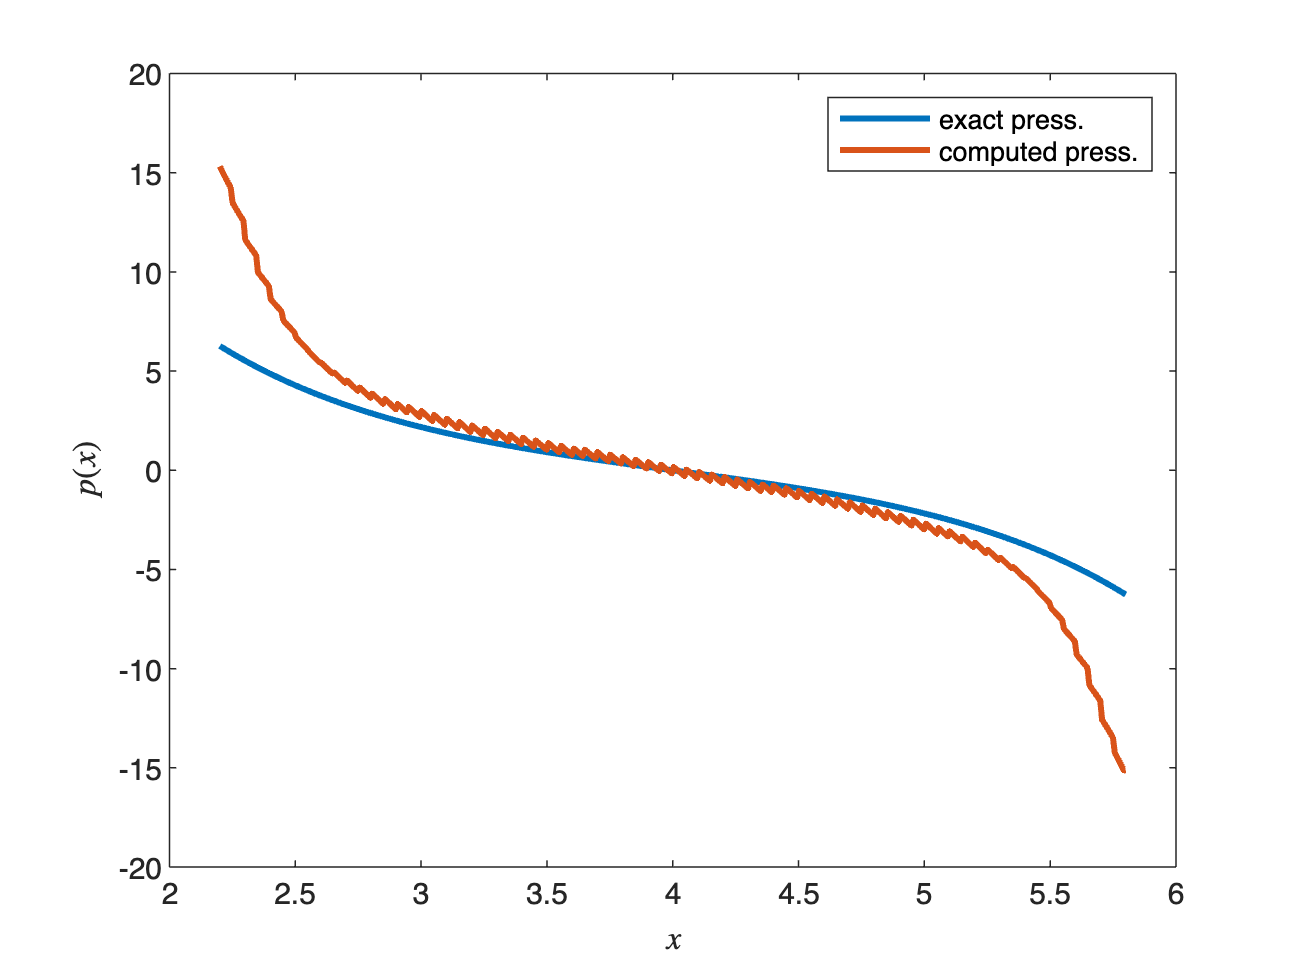


% Step 4: compute velocity everywhere using the computed forces

% Points where velocity will be computed within the channel (target points)
% We will only compute the pressures in the permeable region in order to
% compare to p_T in exact solution.
x1 = linspace(c+0.2,L+c-0.2,Nx1)'; % x-coords of points where computing pressure
x2 = 2*H*ones(size(x1))-0.2;       % y-coords of points where computing pressure
                                   % only computing along permeable portion of top wall

dx_g = x1(2)-x1(1); %(xx1(end)-xx1(1))/Nx1;
dy_g = x2(2)-x2(1); %(xx2(end)-xx2(1))/Nx2;

% computed pressure
%p = RegStokeslets2D_forcetopressure([y1,y2], ftemp, [x1, x2], ep, mu, blob_num, wt);
% Define tangent vectors
tangent_top = zeros(length(stb),2); % unit tangent for top:
tangent_top(:,1) = -1;
tangent_bot = zeros(length(stb),2); % unit tangent for bottom
tangent_bot(:,1) = 1;
tangent_left = zeros(length(slr),2); % unit tangent for left  wall 
tangent_left(:,2) = -1;
tangent_right = zeros(length(slr),2); % unit tangent for right wall 
tangent_right(:,2) = 1;
% tangent on full boundary
tangents = [tangent_top; tangent_bot; tangent_left; tangent_right];

p = RegStokeslets2D_forcetopressure_gauss([y1,y2], ftemp, [x1, x2], ep, mu, beta, blob_num, normals, tangents, wt);

% Exact pressure
xm = (L + 2*c)/2;
alpha = sqrt(3*mu*Da/(H^3));
gamma = -G/(alpha*cosh(alpha*L/2));

pT = @(x)gamma*sinh(alpha*(x - xm));
p_exact = pT(x1);

plot(x1, p_exact, 'LineWidth', 2)
hold on
plot(x1, p, 'LineWidth', 2)
legend('exact press.', 'computed press.')
xlabel('$x$', 'Interpreter', 'Latex')
ylabel('$p(x)$', 'Interpreter', 'Latex')